clear 
clc 
close all

% readmatrix('Flight_data\20231102_DynamicTest_01.xlsm')
table = readtable('Flight_data\20231102_DynamicTest_01.xlsm')

table = 331×30 table
          UTC          Pack_count    IMUTemp      q0           q1             q2          q3        Roll      Pitch        Yaw         RollRate      PitchRate     YawRate         AccX           AccY          AccZ       RealAccX      RealAccY      RealAccZ    PosX    PosY    PosZ     Long     Lat    Height       VelX         VelY       VelZ     RSSI    SNR 
    _______________    __________    _______    ___

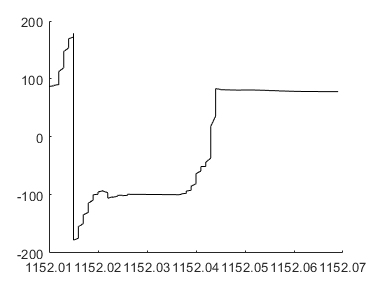

% now = yyyymmdd(datetime)
% a = datetime('now')
% time = a.Minute*60+a.Second;
% now = datenum(table.UTC(1))
h = animatedline();
for i=1:length(table.UTC)
    a = datetime('now');
time = a.Minute*60+a.Second;
%     now = datenum(table.UTC)
%     plot(table.Pitch(i),table.Yaw(i))
%     drawnow
%     hold on
%     grid on
addpoints(h,time,table.Roll(i))
drawnow limitrate
if i ==100
    clearpoints(h)
end
% hold on
% grid on
end